# Rainfall-to-Reservoir Efficiency Visualization for GreenSpout Irrigation

Rainwater harvesting is a growing market in urban water management, sustainable agriculture and smart irrigation

This project helps homeowners can size their rainwater harvesting systems. companies  like irrigation or tank manufacturers estimate ROI. And Urban planners can evaluate water security. And startups  can design tools for customers. So, this project has an objective to model how rainfall interacts with rooftop harvesting systems, compute how much usable water is produced, and simulate tank storage dynamics under real climate data. The project quantifies rainfall, household water storage stability, long term water autonomy based on system design and impact of roof size and tank capacity. The dataset used for this project is 115 years of monthly rainfall data for all indian subdivisions, We filter one subdivision to ensure the model uses consistent geographical climate data. Rainfall varies massively by region, subdivision helps to ensure climate specific simulation.The monthly breakdown reveals peak harvest periods-> when tanks overflow, dry months-> when water shortages occur. The time-series enables trend analysis, extreme event detection, predictive maintenance schedules for tanks.Converting the units helps to make the model becomes internationally usable. For example Europe uses liters and meter square, while US uses gallons & ftsquare.

Compute Harvesting Rainwater


$$yield (L) = rain(mm)\, x\, roof\,area(m^2) \,x\,runoff$$


rainfall depth (mm) x surface area gives volume, Runoff coefficient (0.85) accounts for losses via evaporation, imperfect drainage, and absorption by roof materials.

water Tank balance model:


$$tank = tank + harvested -(30 \,\times\,daily\,use)$$


this helps to add newly harvested water each month, subtract consumption and prevent negative water, exceeding tank capacity. On the interactive rainwater harvesting decision support tool that allows users to explore how tank capacity  and roof area influence long term water supply. By simulating rainfall from 1900-2000 and dynamically updating  graphs as sliders are adjusted, the system visually demonstrates hydrological behavior, seasonal variability, and design trade-offs. The tool supports both scientific understanding and practical decision - making for sustainable water management.

clc; clear; close all;
data = readtable("C:\Users\Dell\Documents\MATLAB\Rainfall project\rainfall in india 1901-2015.csv",VariableNamingRule="preserve");
summary(data);


data: 4116×19 table

Variables:

    SUBDIVISION: cell array of character vectors
    YEAR: double
    JAN: double
    FEB: double
    MAR: double
    APR: double
    MAY: double
    JUN: double
    JUL: double
    AUG: double
    SEP: double
    OCT: double
    NOV: double
    DEC: double
    ANNUAL: double
    Jan-Feb: double
    Mar-May: double
    Jun-Sep: double
    Oct-Dec: double

Statistics for applicable variables:

                   NumMissing        Min            Median             Max               Mean             Std     

    

head(data);

             SUBDIVISION             YEAR     JAN      FEB      MAR      APR      MAY      JUN      JUL      AUG      SEP      OCT      NOV      DEC     ANNUAL    Jan-Feb    Mar-May    Jun-Sep    Oct-Dec
    _____________________________    ____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    ______    _______    _______   


location = "ANDAMAN & NICOBAR ISLANDS";
subset  = data(strcmp(data.SUBDIVISION, location), :);

% Extracting monthly rainfall

monthlyRain = subset{:, {'JAN','FEB','MAR','APR','MAY','JUN','JUL','AUG','SEP','OCT','NOV','DEC'}};

% timeline creation
years = subset.YEAR;
numYears = length(years);

years_expanded = kron(years, ones(12,1)); % repeats each year 12 times
months_expanded = repmat((1:12)', numYears, 1); % generates months 1-12 for every year
dates = datetime(years_expanded, months_expanded, 1); % creates real date objects

rain_mm = monthlyRain(:);
% constants
runoff_coeff = 0.85;
daily_use_L = 20;



## Building Interactive UI

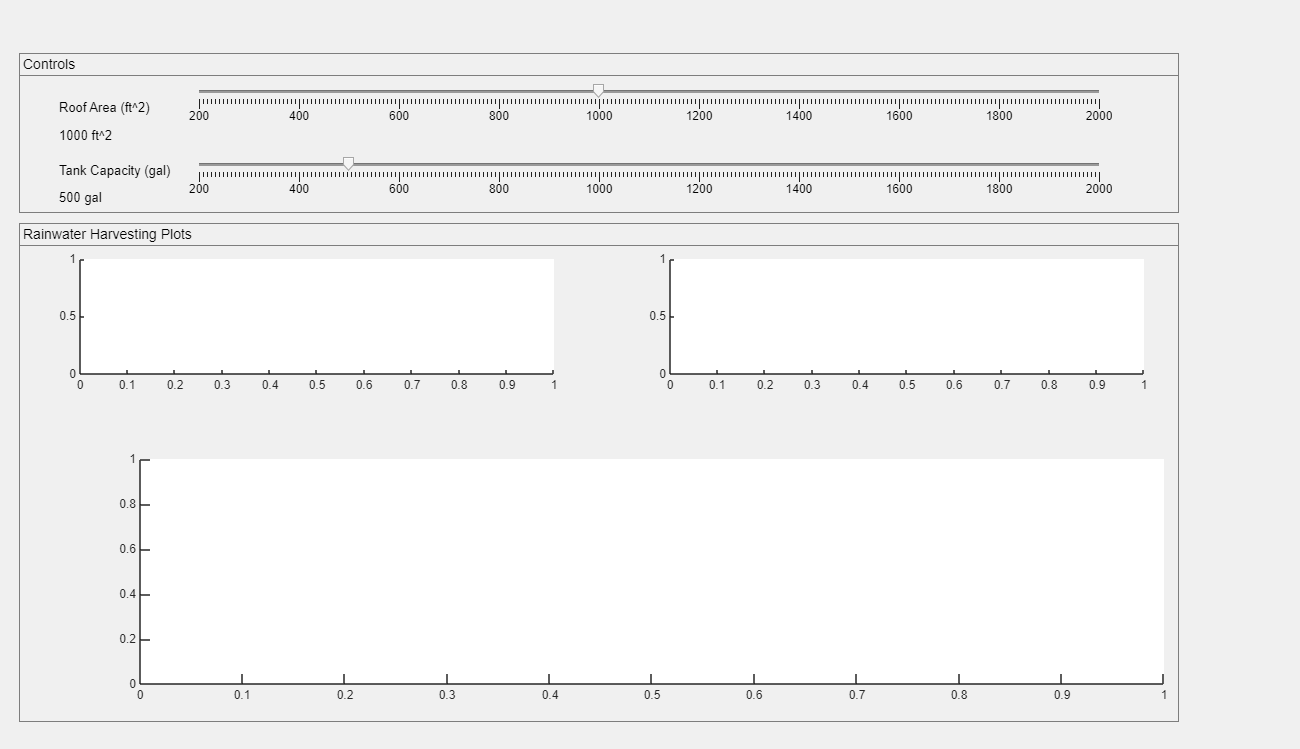


ui = uifigure('Name','Rainwater Harvesting Simulation','Position',[10 0 1300 900]);

% Panels
p1 = uipanel(ui,"Title",'Controls','FontSize',14,'Position',[20 665 1160 170]);
p2 = uipanel(ui,"Title",'Rainwater Harvesting Plots','FontSize',14,'Position',[20 35 1160 620]);

% Sliders
uilabel(p1,"Text",'Roof Area (ft^2)','Position',[40 105 200 20],'FontSize',13);
roof_label = uilabel(p1,"Text",'1000 ft^2','Position',[40 75 200 20],'FontSize',13);

roof_slider = uislider(p1,'Limits',[200 2000],'Value',1000,...
    'Position',[180 130 900 3],...
    'MajorTicks',200:200:2000,...
    'ValueChangingFcn',@(src,event) updatePlots(src,event));

uilabel(p1,'Text','Tank Capacity (gal)','Position',[40 35 200 20],'FontSize',13);
tank_label = uilabel(p1,"Text",'500 gal','Position',[40 5 200 20],'FontSize',13);

tank_slider = uislider(p1,'Limits',[200 2000],'Value',500,...
    'Position',[180 50 900 3],...
    'MajorTicks',200:200:2000,...
    'ValueChangingFcn',@(src,event) updatePlots(src,event));
% Axes

ax1 = uiaxes(p2,'Position',[40 330 500 140]); % Rainfall
ax2 = uiaxes(p2,'Position',[630 330 500 140]); % Tank
ax3 = uiaxes(p2,'Position',[100 20 1050 250]);  % Heatmap


% callback function

function updatePlots(~,~)

    % Access base workspace variables
    rain_mm = evalin('base','rain_mm');
    dates = evalin('base','dates');

    runoff_coeff = evalin('base','runoff_coeff');
    daily_use_L = evalin('base','daily_use_L');

    ax1 = evalin('base','ax1');
    ax2 = evalin('base','ax2');
    ax3 = evalin('base','ax3');

    roof_label = evalin('base','roof_label');
    tank_label = evalin('base','tank_label');
    roof_slider = evalin('base','roof_slider');
    tank_slider = evalin('base','tank_slider');

% Update labels
roof_label.Text = sprintf('%d ft^2', round(roof_slider.Value));
tank_label.Text = sprintf('%d gal', round(tank_slider.Value));

% Convert units

roof_m2 = roof_slider.Value * 0.092903;
tank_L = tank_slider.Value * 3.78541;

% Compute Yield

yield_L = rain_mm .* roof_m2 .* runoff_coeff;

% Tank simulation
tank = 0;
tank_history = zeros(length(yield_L),1);

for i = 1:length(yield_L)
    tank = tank + yield_L(i) - daily_use_L*30;
    tank = max(min(tank, tank_L),0);
    tank_history(i) = tank;

end

% Heatmap (Roof x Tank)

roofVals = 200:200:2000;
tankVals = 200:200:2000;
daysAutonomy = zeros(length(roofVals), length(tankVals));

for i = 1:length(roofVals)
    for j = 1:length(tankVals)
        r_m2 = roofVals(i) * 0.092903;
        t_L = tankVals(j) * 3.78541;

        tank_tmp = t_L;
        days = 0;

        for k = 1:length(yield_L)
            harvested = rain_mm(k) * r_m2 * runoff_coeff;

            tank_tmp = tank_tmp + harvested - daily_use_L * 30;
            tank_tmp = max(min(tank_tmp, t_L), 0);

            if tank_tmp > 0
                days = days + 30;
            end

        end

        daysAutonomy(i,j) = days;
    end
end

% Update Plots

% Panel A
bar(ax1, dates, yield_L/1000);
title(ax1, 'Monthly Rainfall Yield');
ylabel(ax1,'Captured Water (m^3)');
grid(ax1,"on");

% Panel B

stairs(ax2, dates, tank_history /1000,'LineWidth',1.5);
title(ax2, 'Citren storage Level Over Time');
ylabel(ax2, 'Tank Volume (m^3)');
grid(ax2,"on");

imagesc(ax3,tankVals, roofVals, daysAutonomy);
set(ax3,'YDir','normal');
colorbar(ax3);
title(ax3,'Days of Autonomy - Water Security Map');
xlabel(ax3,'Tank Capacity (gal)');
ylabel(ax3, 'Roof Area (ft^2)');
colormap(ax3,'summer');
hold(ax3,"on");
plot(ax3,...
    tank_slider.Value,...
    roof_slider.Value,...
    'rp',...
    'MarkerSize',18,...
    'MarkerFaceColor','red');
hold(ax3,'off');

end

## **Conclusion**

This project successfully processes real indian rainfall data, converts rainfall into usable harvested water, simulates realistic tank filling/ emptying, and provides interactive MATLAB UI with live sliders. Updates all plots dynamically in real time.The visualizations  captured rainwater yield, tank storage dynamics and days of autonomy heatmap. So it helps users visually understand water security and system performance for different designs.To transform raw rainfall data into a decision support tool that can guide citizens, engineers, and sustainability managers in designing cost-effective rain water harvesting systems. Rainfall patterns fluctuate across decades, rainfall is lower in early 1900-1920, causing low capture. After 1940, rainfall increases more consistently, so the total captured water rises sharply. Once rainfall increases, the tank fills more frequently, and captured water graphs show a rising curve. A fixed system size may perform poorly in dry decades but extremely well in wet periods. Decision makers should size systems based on multiple years of climate data, not a single year. When we see Cistern storage level over time shows waves from 1900 to 1940, then becomes full after 1940 till 2000. Between 1900 and 1940 it is under capacity: rainfall < household demand -> tank empties often-> wavy pattern. From 1940 onward, it is over-capacity: rainfall > household demand -> tank always full-> flat line at 200 L. This indicates the tank no longer influences the system because natural rainfall is supplying more than the demand, so the limiting factor becomes tank size only, not rainfall.A smaller tank would provide the same performance post-1940. However, if the goal is resillience, a larger tank gives longer autonomy during droughts. Increasing roof area(with tank 200) makes tank volume reach a constant full level after 1940. When we see rainfall peaks in Specific Months, e.g., October 76.4 mm, November 47.8 mm, March 107.4 mm at 1960, this indicates rainfall fluctuates across months. Some months (e.g., March, October) supply significantly more water. This seasonality explains why the tank behaves differently throughout the year. From the heatmap, as both roof area and tank capacity increases -> water captured increases. But after certain limits, most combinations show the same(Yellowish) value, this reveals a saturation region where further increases have little added benefit. Very pale region is undersized systems. 